sensitivity = 0.99;
specificity = [0.99,0.999,0.9999,0.99999];
prevalence = 0:0.00001:0.5;

## Formula


$$P(\text{sick } | \text { test positive}) = \frac{P(\text{sick }\land \text{ test positive})}{P(\text{test positive})} $$



$$P(\text{sick } \land \text{ test positive}) = \text{prevalence} \cdot \text{sensitivity}$$



$$P(\text{healthy }\land \text{ test positive}) = (1- \text{prevalence}) \cdot \text{specificity}$$



$$P(\text{test positive}) = P(\text{test positive }\land \text{ sick}) +P(\text{test positive }\land \text{ healthy} )
$$


In the end we get


$$P(\text{sick }| \text{ test positive}) = \frac{\text{prevalence}\cdot \text{sensitivity}}{\text{prevalence}\cdot \text{sensitivity} + (1-\text{prevalence}) \cdot (1-\text{specificity})}$$


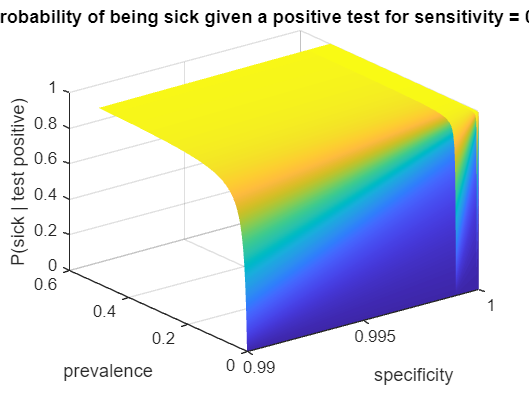

pSickIfPositive = @(sensitivity,specificity,prevalence) prevalence.*sensitivity ./ (prevalence.*sensitivity + (1-prevalence).*(1-specificity));

specMatrix = ones(size(prevalence))' * specificity;
prevMatrix = (ones(size(specificity))' * prevalence)';

pMatrix = pSickIfPositive(sensitivity,specMatrix,prevMatrix);

figure(1)
surf(specMatrix,prevMatrix,pMatrix,EdgeColor="none")
xlabel("specificity")
ylabel("prevalence")
zlabel("P(sick | test positive)")
title("Probability of being sick given a positive test for sensitivity = 0.99")

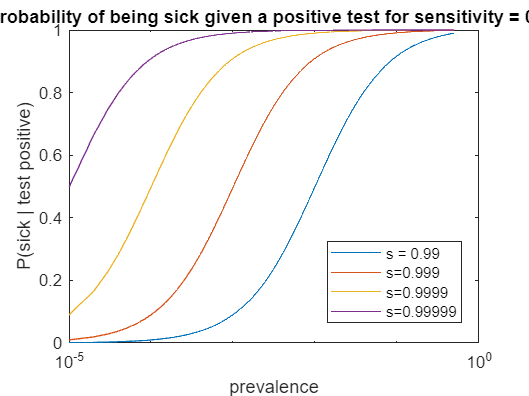


index = 1;
figure(2);
clear p;
for s = specificity
    p(index,:) = pSickIfPositive(sensitivity,s,prevalence);
    index = index + 1;
end

semilogx(prevalence,p(1,:),prevalence,p(2,:),prevalence,p(3,:),prevalence,p(4,:))
legend("s=0.99","s=0.999","s=0.9999","s=0.99999")
xlabel("prevalence")
ylabel("P(sick | test positive)")
title("Probability of being sick given a positive test for sensitivity 0.99 and specificity s")